# Variable thermal conductivities

clear
set_demo_defaults
rho = 2700;   % ave. crustal density [kg/m^3]
H0 = 9.6e-10; % heat production near surface [W/kg]
h = 35e3;     % ave. depth of crust [m]
T0 = 14;      % Surface Temperature [C]
hr = 10e3;    % decay depth of radiogenic heat production
qm = 17e-3;   % Mantle heat flow   [mW/m/K]

## Variation in crustal thermal conductivity

So far we have considered the thermal conductivity, $\kappa$, of the crust to be constant. In reality, $\kappa$varies with location due to changes in rock composition. One major change with depth in the continental crust is a progressive change from so-called [felsic](https://en.wikipedia.org/wiki/Felsic) rocks in the upper crust to so-called [mafic](https://en.wikipedia.org/wiki/Mafic) rocks in the lower crust.

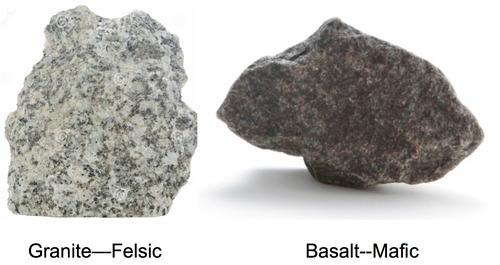

Felsic rocks have higher values of radiogenic heat production than mafic rocks, which explains the decay of radiogenic heat production in the crust, at least partially. While both rock types have a large range in thermal conductivities, mafic rock tend to have higher conductivities than felsic rocks. Here we assume the two following values:

kappa.felsic = 3.5; % thermal conductivity of felic rocks [W/(m K)]
kappa.mafic = 2.5; % thermal conductivity of mafic rocks  [W/(m K)]

We assume that the variation of the two rock types with depth mimicks the decay of the heat production with depth. Therefore the volume fractions of the rock-types vary with depth as follows

hr = 10e3; 
phi.felsic = @(z) exp(-z/hr);
phi.mafic = @(z) 1-phi.felsic(z);

We assume that the mean thermal conductivity of the rock is given by the volume fraction-weighted average of the thermal conductivities of the two rock types

$\bar{\kappa}(z) = \phi_{\mathrm{felsic}}(z)\,\kappa_{\mathrm{felsic}} + \phi_{\mathrm{mafic}}(z)\,\kappa_{\mathrm{mafic}}$.

Therefore we define the an anaoymous Matlab function for the thermal conductivity

kappa.mean = @(z) phi.felsic(z).*kappa.felsic + phi.mafic(z).*kappa.mafic;

The figure shows the vertical variation of the rock types and the thermal conductivity

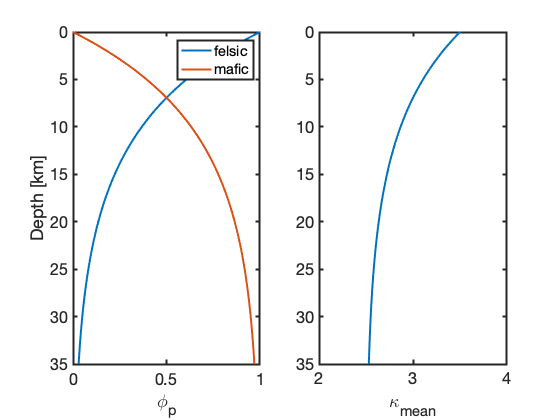

zplot = linspace(0,h,1e2);
subplot 121
plot(phi.felsic(zplot),zplot/1e3), hold on
plot(phi.mafic(zplot),zplot/1e3), hold off
set(gca, 'YDir','reverse','fontsize',16)
ylabel('Depth [km]')
xlabel('\phi_p')
legend('felsic','mafic')

subplot 122
plot(kappa.mean(zplot),zplot/1e3)
set(gca, 'YDir','reverse')
xlabel('\kappa_{mean}')
xlim([2 4])

## Solving problem with variable coefficients

Once the thermal conductivity, $\kappa
$, varies with location it has to remain inside the divergence

$-\nabla\cdot\left(\bar{\kappa}(\mathbf{x})\nabla T \right) = \rho H_0e^{-z/h_r}$.

To account for variable thermal conductivity in the discrete approximation we introduce the diagonal conductivity matrix, `Kd`, so that the discete linear differential operator is given by` L = -D*Kd*G`. and the heat flux by `q = -Kd*G*u`. The conductivity matrix is Nf by Nf and contain the thermal conductivity associated with each face. The conductivity matrix is diagonal, because it simply multiplies the temperature gradient on each face with the appropriate conductivity.

In general, thermal conductivites are given in the cell centers, because they often depend on solution variable such as temperature, composition (radiogenic heating) or viscous dissipation. Therefore, the diagonal of Kd contains the harmonic average of the thermal condutivietes of the two adjacent cells

$\mathrm{Kd}_{ii} = \frac{1}{\frac{1}{\kappa_i}+
\frac{1}{\kappa_{i+1}}} $,

where we have assumed that the grid spacing is constant in the x-direction. The harmonic average is approriate, because heat flow is *across* layers of different conductivity. 

## Numerical solution

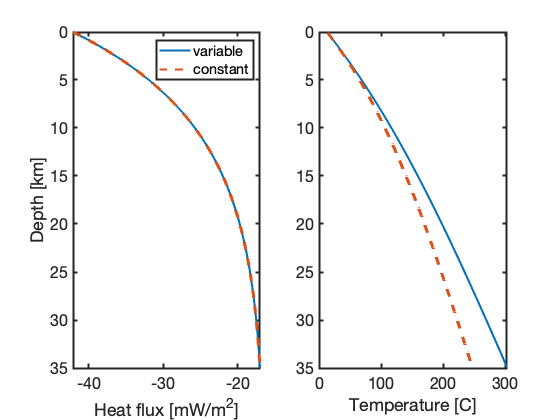

Grid.xmin = 0; Grid.xmax = h; Grid.Nx = 200; % Note: here x is the depth
Grid = build_grid(Grid);
% 2) Build operators and r.h.s.
[D,G,I] = build_ops(Grid);
Kd = comp_mean(kappa.mean(Grid.xc'),-1,1,Grid);
L_var = -D*Kd*G; L_const = -D*kappa.felsic*G;
fs = rho*H0*exp(-Grid.xc/hr);
% 3) Define location and value of BC's
BC.dof_dir   = Grid.dof_xmin;   % Dirichlet BC at x = 0
BC.dof_f_dir = Grid.dof_f_xmin;
BC.g         = T0;    % Using analytic solution to set BC in cell center
BC.dof_neu   = Grid.dof_xmax;   % Neuman BC at x = h
BC.dof_f_neu = Grid.dof_f_xmax;
BC.qb        = qm;             % Mantle heat flow (positve, i.e. into the crust)
[B,N,fn] = build_bnd(BC,Grid,I);

% 4) Variable conductivity solution
T_var = solve_lbvp(L_var,fs+fn,B,BC.g,N);
q_var = comp_flux(D,Kd,G,T_var,fs,Grid,BC);

% 4) Variable conductivity solution
T_const = solve_lbvp(L_const,fs+fn,B,BC.g,N);
q_const = comp_flux(D,kappa.felsic,G,T_const,fs,Grid,BC);

subplot 121
plot(q_var*1e3,Grid.xf/1e3,'-',q_const*1e3,Grid.xf/1e3,'--')
set(gca, 'YDir','reverse','fontsize',16)
ylabel('Depth [km]')
xlabel('Heat flux [mW/m^2]')
legend('variable','constant')

subplot 122
plot(T_var,Grid.xc/1e3,'-',T_const,Grid.xc/1e3,'--')
set(gca, 'YDir','reverse','fontsize',16)
xlabel('\phi_p')
xlabel('Temperature [C]')